
% clear;
% clc;


% 文件保存位置
savelocation = 'D:\\DataSets\\EEG_data\\eeg_music_7';
% 无用的被试
invalid_chan = [2,4,5,14,18,22,29];
Fs = 200;                   %采样率
deltat = 100*Fs/1000;       % 延迟100ms = 20samples
musicLen = 30;              % music length
musicNum = 16;
numLocation = 62;

% 被试数量
num_sub = 31;
count = 1;
for i = 3:3
    % 舍弃有损坏的数据
    if any(invalid_chan == i) == 1
       continue;
    end
    disp(i);
    EEG = pop_loadset('filename',['sub_', num2str(i),'_f_a_ica.set'],'filepath',savelocation);
    data_all = EEG.data;
    event = EEG.event;
    
    for k = 1 : musicNum
        music_st(count, k) = struct('eo1', zeros(numLocation,1),'music', zeros(numLocation,1), ...
            'eo2', zeros(numLocation,1), 'valence', 0, 'arousal', 0,'subject',i);
    end
    mIndex = 0;
    disp('extract')
    for k = 1:length(event)
        e = event(k);
        e.latency = round(e.latency);
        % 15s of eo (code 51~66) 音乐播放前15s静息脑电
        if e.type >= 51 && e.type <= 66
            mIndex = e.type - 50;
            music_st(i,mIndex).eo1 = data_all(:,e.latency + deltat:e.latency+Fs*15+deltat-1);
        end
        
        %  30s of music (code 11~26) 30s音乐播放时间
        if e.type >= 11 && e.type <= 26
            music_st(i,mIndex).music = data_all(:,e.latency+deltat:e.latency+Fs*musicLen+deltat-1);
        end
        
        %  15s of eo (code 71~86) 音乐播放后15s静息脑电
        if e.type >= 71 && e.type <= 86
            music_st(i,mIndex).eo2 = data_all(:,e.latency+deltat:e.latency+Fs*15+deltat-1);
        end
        
        %  questionnaire (code 31~33)愉悦度与唤醒度
        if e.type == 31
            music_st(i,mIndex).valence = event(k+1).type;
        end
        if e.type == 32
            music_st(i,mIndex).arousal = event(k+1).type;
        end
    end
end

     3



pop_loadset(): loading file D:\DataSets\EEG_data\eeg_music_7\sub_3_f_a_ica.set ...
Reading float file 'D:\DataSets\EEG_data\eeg_music_7\sub_3_f_a_ica.fdt'...
Scaling components to RMS microvolt


extract


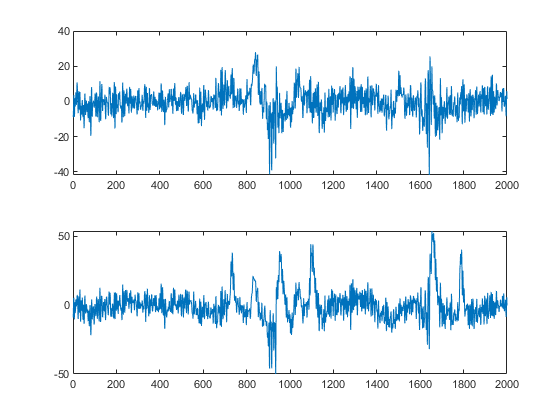

figure(1)
subplot(2,1,1)
plot(data1);
subplot(2,1,2)
plot(data2)